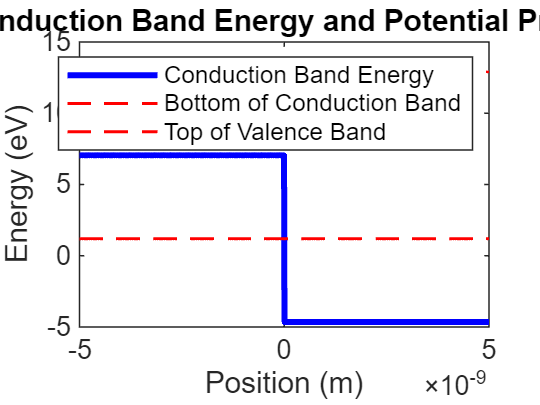

%%Can be expanded Upon for modeling Fermi Energy within the well
% Define constants
%%Sammy Masters
hbar = 1.0545718e-34;  % Reduced Planck constant (m^2 kg / s)
m_e = 9.10938356e-31;  % Electron mass (kg)
eps = 8.854187817e-12; % Vacuum permittivity (F/m)

% Define potential profile (eV)
V0 = 1.2;     % Potential at the bottom of the conduction band
Vg = 11.7;   % Potential gap between the conduction and valence bands

% Define parameters for the potential profile
L = 5e-9;   % Length of the semiconductor region (m)
x = linspace(-L, L, 1000); % Spatial grid

% Effective mass approximation (arbitrary units)
m_eff = 0.1 * m_e;  % Effective mass of the electron

% Solve the Schrödinger equation for the conduction band
E_conduction = zeros(size(x));
for i = 1:length(x)
    if x(i) <= 0
        E_conduction(i) = V0 + Vg/2;
    else
        E_conduction(i) = V0 - Vg/2;
    end
end

% Calculate the band gap
band_gap = max(E_conduction) - min(E_conduction);

% Plot the potential profile and conduction band energy
figure;
plot(x, E_conduction, 'b', 'LineWidth', 2);
hold on;
plot(x, ones(size(x)) * V0, 'r--', 'LineWidth', 1); % Plot bottom of conduction band
plot(x, ones(size(x)) * (V0 + Vg), 'r--', 'LineWidth', 1); % Plot top of valence band
xlabel('Position (m)');
ylabel('Energy (eV)');
title('Conduction Band Energy and Potential Profile');
legend('Conduction Band Energy', 'Bottom of Conduction Band', 'Top of Valence Band');


% Display the band gap
disp(['Band Gap: ', num2str(band_gap), ' eV']);

Band Gap: 11.7 eV
